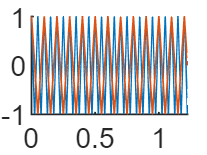

samples = 50;           

Fs = 40;
Ts = 1 / Fs;

t = linspace(0, Ts * samples, samples + 1); t(end) = [];

s1 = cos(2 * pi * 100 * t);
s2 = cos(2 * pi * 50 * t);

figure
hold on
plot(t, s1)
plot(t, s2)
xlim([t(1) t(end)])

## Challenge

## Part 1

clear
close all
% Use audioread as wavread is out of date
[sig, Fs] = audioread('Chopin.wav'); 
sig = sig.'; % change to row vector

## Part 2

% File sampled at 44100 Hz
samples = length(sig);
Ts = 1 / Fs;

## Part 3

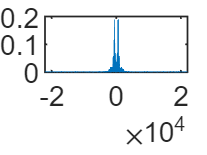

t = linspace(0, samples * Ts, samples + 1); t(end) = [];
f = linspace(-Fs/2, Fs/2, samples + 1); f(end) = [];

SIG = fft(sig);

figure
plot(f, abs(fftshift(SIG)) * Ts)

## Part 4

% Find Nyquist rate
fmax = 2.5e3; % Negligible content
fNyquist = 2 * fmax;

## Part 5

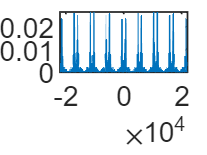

% Do it this way so that MATLAB shows the repeated versions and it doesnt
% do an anti aliasing filter internally
pulse_train = zeros(1, samples);
pulse_train(1:floor(Fs/fNyquist):end) = 1;

sig_sample = sig .* pulse_train;
SIG_SAMPLE = fft(sig_sample);

figure
plot(f, abs(fftshift(SIG_SAMPLE)) * Ts)

## Part 6

% Show small vector here proves we need to minus 1
% zero = 3;
% 
% a = 1:10;
% a(1:zero) = 0;
% a(end:-1:(end-zero)) = 0;
% 
% b = 1:10;
% b(1:zero) = 0;
% b(end:-1:(end-(zero-1))) = 0; 

% Receiver reconstruction filter
SIG_SAMPLE_filter = abs(f) < fmax;

anti_alias_filter = abs(f) < fmax;

% filter at transmitter
SIG_PREP = ifftshift(ifftshift(SIG) .* anti_alias_filter);
sig_prep = ifft(SIG_PREP) * Fs;

% Sample
sig_prep_sample = sig_prep .* pulse_train;

% filter at receiver
SIG_PREP_SAMPLE = ifftshift(fftshift(fft(sig_prep_sample)) .* anti_alias_filter);
sig_prep_sample = ifft(SIG_PREP_SAMPLE);

## Part 7

%{
Removal of higher frequency components is perhaps more notice-able in this 
case as the audio sounds dull compared to the original, which has slightly 
better clarity. Aliasing effects are perhaps more difficult to discern, as 
the overlapping regions of the spectrum do not introduce much distortion 
into the main portions of the spectrum that are below around 830 Hz.
%}

## Part 8

%{
Using an even lower sampling frequency will allow you to more
easily listen to the effects of aliasing when the more important sections of
the spectrum begin to overlap. (Try with a sampling frequency of around 3/4
Nyquist rate.)
%}
% 
% % New Nyquist rate
% Nyquist2 = ;
% % Resample the signal
% samp_A = ;
% Samp_A = ;
% % Smaller filter to reduce the amount of error, filter till 3/4*fmax
% AFilt = ;
% % Reconstruct the signal
% SigA_recon = ;
% sigA_recon = ;
% % Normalise the signal
% sigA_recon_norm = ;
% % Listen



## Part 9

%{
Design an anti-aliasing filter to account for the new fmax due to 3/4
Niquist rate sampling. Apply to original spectrum and resample at 3/4
Nyquist rate.
- Unless otherwise stated, filter is ideal (made up of zeros and ones)
- Multiply filter to fft() values, not just the abs() values
- If fftshift included in calculations, ifftshift is required.
%}


## Part 10

% sigAA_recon_norm = ;